addpath Function\
addpath Template_data\ 

# ** Copy your code here:**


% One-side:  0.95  1-0.05
% Two-side:  u2u("95s")  u2u("5a")
conf=confidence_tool();

[sig1,sig2,e1,e2]=deal(0.0015,0.0015,34,34);
[mean1,s1,f1]=deal(u2u("3.5mm"),u2u("0.81m"),50);
[mean2,s2,f2]=deal(u2u("3.5mm"),u2u("1.21m"),50);

[a,b]=conf.get_interval_f(u2u("2a"),s1,s2,f1,f2);

The interval boundary is [0.4795,0.9345]
The confidence Level = 98.00%, Error probability = 2.00%


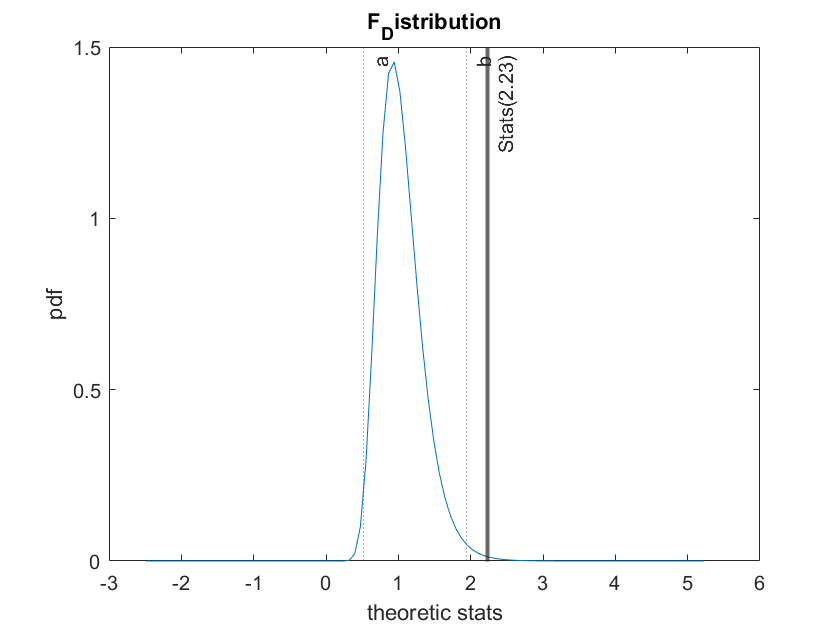

Test Statistic (s2/s1)^2: 2.23 ,Critical value=[0.51,1.95]
1,Reject the null hypothesis H0: Same
1,Reject HC: Significant smaller with S=99.00%
2.Choose hypothesis HA: Significant Bigger with S=99.00%
2.Choose hypothesis HB: Significant difference with S=98.00%


stats=conf.statistic_test_f(u2u("2a"),s1,s2,f1,f2);


addpath Function/
addpath Semester_2nd_data/

% One-side:  0.95  1-0.05
% Two-side:  u2u("95s")  u2u("5a")
conf=confidence_tool();
[sig1,e1]=deal(1,0);
[mean1,s1,f1]=deal(8.73,sqrt(0.35),14);
[mean2,s2,f2]=deal(8.68,sqrt(0.40),16);

[a,b]=conf.get_interval_t_delta(u2u("5a"),mean1,mean2,s1,s2,f1,f2);

The interval boundary is [-0.444,0.444]
The confidence Level = 95.00%, Error probability = 5.00%


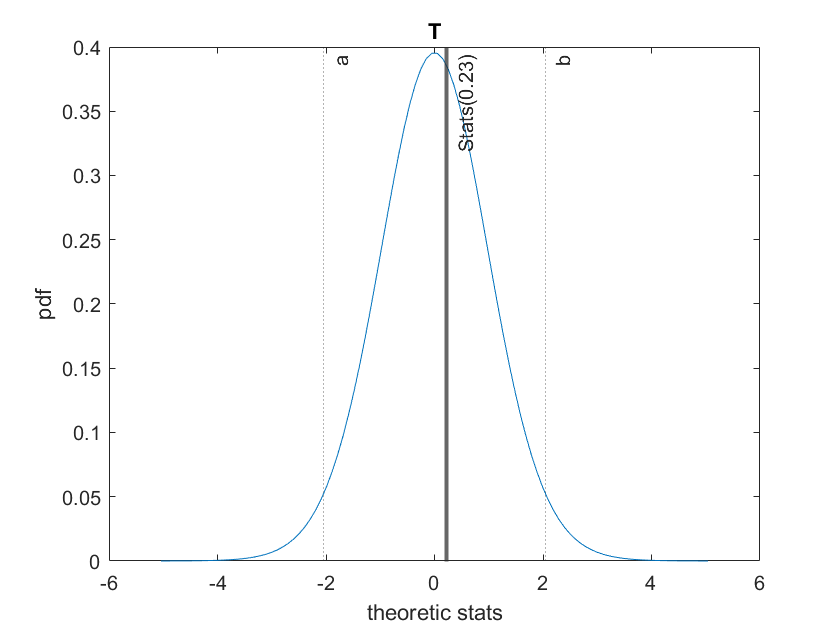

Test Statistic: 0.23 ,Critical value=[-2.04,2.04]
Fails to reject the null hypothesis H0


stats=conf.statistic_test_t_delta(u2u("5a"),mean1,mean2,s1,s2,f1,f2);

# **Note:**

**One Side Problem:**

a=5 s=95 in lecture 

0.95 in matlab function

u2u("10a) u2u("90s) in my code

**Two Side Problem:**

a=5 s=95 in lecture 

0.975 in matlab function

u2u("5a) u2u("95s) in my code